Ki = 3.33;
Kp = 5.66;
Kd = 4.14;

F = tf(1, [1, 1])

F =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



G = tf(3, [1, 4, 5, 0])

G =
 
          3
  -----------------
  s^3 + 4 s^2 + 5 s
 
Continuous-time transfer function.



Gc = tf([Kd, Kp, Ki], [1, 0])

Gc =
 
  4.14 s^2 + 5.66 s + 3.33
  ------------------------
             s
 
Continuous-time transfer function.




T = F * feedback(G * Gc, 1)

T =
 
              12.42 s^2 + 16.98 s + 9.99
  ---------------------------------------------------
  s^5 + 5 s^4 + 21.42 s^3 + 34.4 s^2 + 26.97 s + 9.99
 
Continuous-time transfer function.



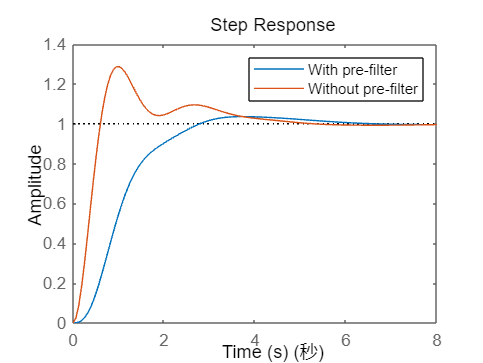


step(T, feedback(G * Gc, 1))
legend(["With pre-filter", "Without pre-filter"])
title("Step Response")
xlabel("Time (s)")
ylabel("Amplitude")

A = [[0, 1, 0, 0];[0, 0, 1, 0];[0, 0, 0, 1]; [-60, -86, -46, -11]];
B = [0;0;0;1];
C = [1, 1, 0, 0];
D = 0;

Plant = ss(A,B,C,D,-1);
Plant.InputName = 'un';
Plant.OutputName = 'yt';

Sum = sumblk('un = u + w');
sys = connect(Plant,Sum,{'u','w'},'yt');

Q = 0.001;
R = 100;
N = 0;

[kalmf, L, P] = kalman(sys,Q,R,N);
size(kalmf)

具有 5 个输出、2 个输入和 4 个状态的状态空间模型。



L

L =     0.9833
  -10.5500
   70.5500
 -376.3000


P = tf([1, 1], [1, 11, 46, 86, 60])

P =
 
                s + 1
  ---------------------------------
  s^4 + 11 s^3 + 46 s^2 + 86 s + 60
 
Continuous-time transfer function.




[K, CL, gamma] = hinfsyn(P, 1, 1);
gamma

gamma = 0

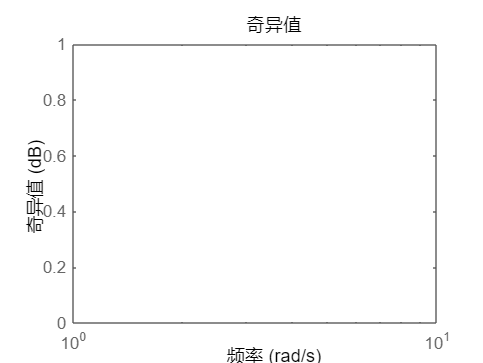


sigma(CL,ss(gamma))